%Test Single File
%fileLocation = workingFiles(image).folder + "/" + workingFiles(image).name;
fileLocation = "./workingImages/starfish_5.jpg"

fileLocation = "./workingImages/starfish_5.jpg"

[mask, original] = pipeline1(fileLocation);

Blue Channel Salt and Pepper Noise


Taking Green Channel
Getting the complement


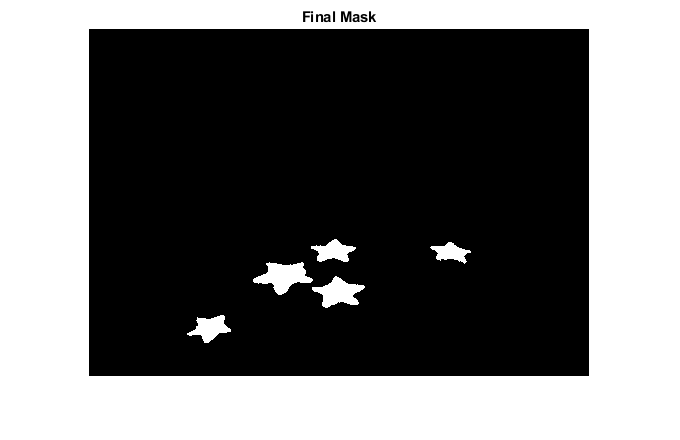

%texAnalysis(mask, original);
bw =  mask - bwareaopen(mask,2500);
bw = bwareaopen(bw, 200);
bw = activecontour(original,bw,200);

figure
imshow(bw);




title("Final Mask");

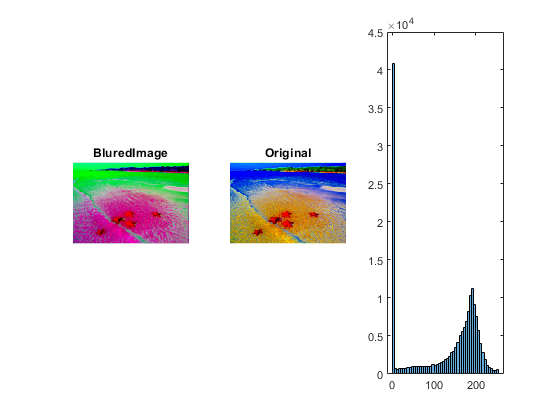

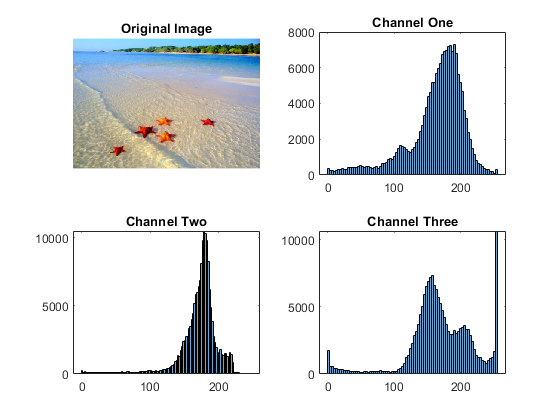

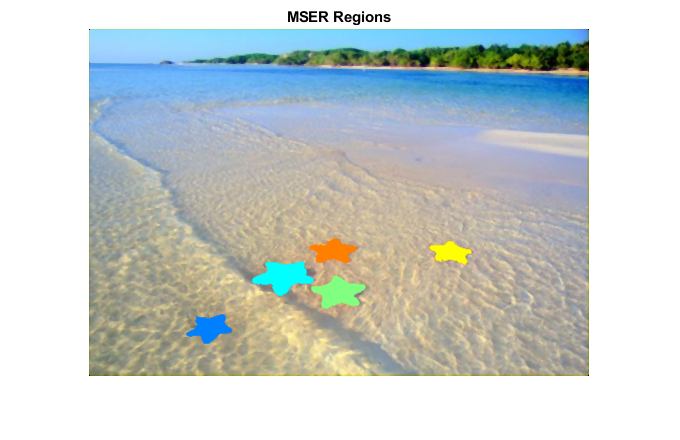

[fullStat, boundingBoxes, NoStarfish] = MSERRegionAnalysis(bw, original);

1: BoudningBox:  X: 164.5 Y: 233.5 Eccentricity: 0.83766 Solidity: 0.74425 Area: 1036
2: BoudningBox:  X: 341.5 Y: 213.5 Eccentricity: 0.8829 Solidity: 0.74121 Area: 464
3: BoudningBox:  X: 223.5 Y: 247.5 Eccentricity: 0.80345 Solidity: 0.73222 Area: 875
4: BoudningBox:  X: 222.5 Y: 210.5 Eccentricity: 0.86337 Solidity: 0.74935 Area: 577
5: BoudningBox:  X: 98.5 Y: 286.5 Eccentricity: 0.77996 Solidity: 0.74156 Area: 637


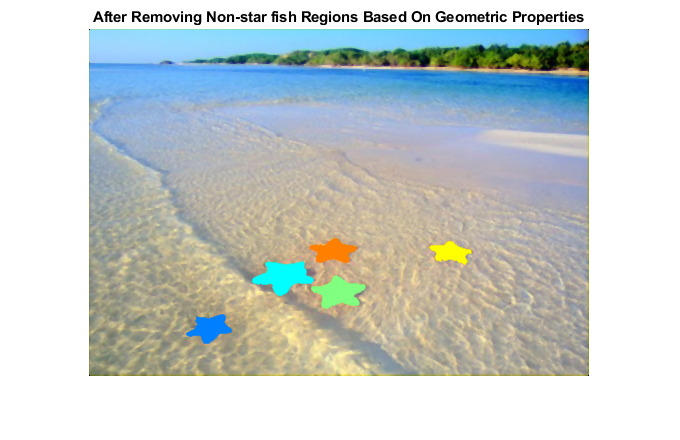

sizeOfBoudingBox = size(boundingBoxes);
if(sizeOfBoudingBox(1) == 0)
    [fullStat, boundingBoxes, NoStarfish] = MSERRegionAnalysis2(bw, original);
    sizeOfBoudingBox = size(boundingBoxes);
end

output = figure;
imshow(original);
hold on;
for x = 1:sizeOfBoudingBox(1)
    
  thisBB = boundingBoxes(x, (1:4));
  text(thisBB(1) + thisBB(3) /2, thisBB(2) - 10,"" + x);
  rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
    

end
hold off;
title("Final Output: There are " + NoStarfish + " Starfish");
mkdir("./" + NoStarfish + "/");

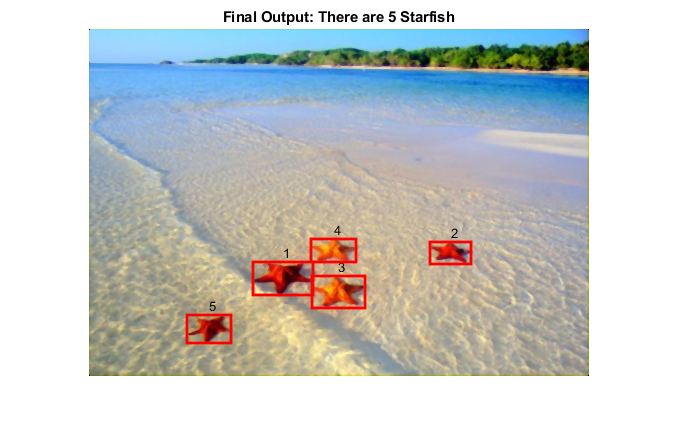

saveas(output, "./" + NoStarfish + "/" + "Test.jpg");